# KOLO

clear
close all
syms s_s
syms w_s
assume(w_s, 'positive')
assume(w_s, 'real')
s_t = tf('s');

%%INPUTS________________________________

%A = [0, 0; 0, 0]; B = [0, 0; 0, 0]; C = [0, 0; 0, 0]; D = [0, 0; 0, 0]
%G_L = ss(A, B, C, D)
%[num, denom] = ss2tf(A, B, C, D)
%G_L = tf(num, demon)

G_L = -1 * tf([1, 2], [1 1]) * tf([1], [1 1]) * tf([1], [1 1]) * tf([1], [1 0.75])

G_L =
 
                   -s - 2
  -----------------------------------------
  s^4 + 3.75 s^3 + 5.25 s^2 + 3.25 s + 0.75
 
Continuous-time transfer function.



[A, B, C, D] = tf2ss(G_L.Numerator{1, 1}, G_L.Denominator{1, 1})

A =    -3.7500   -5.2500   -3.2500   -0.7500
    1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000         0


B =      1
     0
     0
     0


C =      0     0    -1    -2


D = 0


%KOLO_______________________________
m1 = 0;
m2 = 1/0.73;
m0 = 0.8;

%%___________________________________________________________

G_s = poly2sym(G_L.Numerator{1, 1}, s_s) / poly2sym(G_L.Denominator{1, 1}, s_s)

$$G\_s = -\frac{s_{s}+2}{{s_{s}}^{4}+\frac{15\,{s_{s}}^{3}}{4}+\frac{21\,{s_{s}}^{2}}{4}+\frac{13\,s_{s}}{4}+\frac{3}{4}}$$

OUTSIDE THE CIRCLE


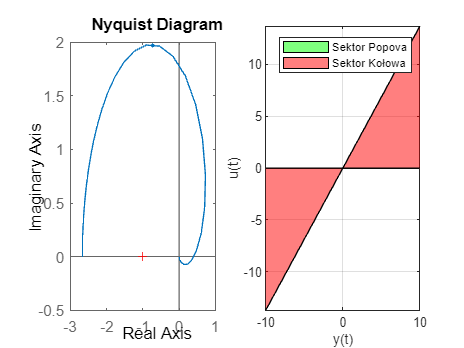


m1m2plot(m1, m2, G_L, 0)


Abm0c = A + m0.*B*C

Abm0c =    -3.7500   -5.2500   -4.0500   -2.3500
    1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000         0


eig(Abm0c)

ans =   -1.6364 + 0.4373i
  -1.6364 - 0.4373i
  -0.2386 + 0.8730i
  -0.2386 - 0.8730i



y = -10:0.1:10;

# SYMS

# POPOV

%POPOV_INPUT______________________________
b = -0.45;
a = 1;
x = linspace(-2, 2);

G_L_w = subs(G_s, s_s, 1i*w_s)

$$G\_L\_w = -\frac{2+w_{s}\,\mathrm{i}}{{w_{s}}^{4}-\frac{15\,{w_{s}}^{3}\,\mathrm{i}}{4}-\frac{21\,{w_{s}}^{2}}{4}+\frac{13\,w_{s}\,\mathrm{i}}{4}+\frac{3}{4}}$$

P_w = simplify(real(G_L_w))

$$P\_w = \frac{4\,\left(7\,{w_{s}}^{4}+29\,{w_{s}}^{2}-6\right)}{{\left({w_{s}}^{2}+1\right)}^{3}\,\left(16\,{w_{s}}^{2}+9\right)}$$

Q_w = simplify(imag(G_L_w))

$$Q\_w = -\frac{4\,w_{s}\,\left(4\,{w_{s}}^{4}+9\,{w_{s}}^{2}-23\right)}{{\left({w_{s}}^{2}+1\right)}^{3}\,\left(16\,{w_{s}}^{2}+9\right)}$$

wQ_wmod = w_s*Q_w

$$wQ\_wmod = -\frac{4\,{w_{s}}^{2}\,\left(4\,{w_{s}}^{4}+9\,{w_{s}}^{2}-23\right)}{{\left({w_{s}}^{2}+1\right)}^{3}\,\left(16\,{w_{s}}^{2}+9\right)}$$


w = logspace(-5, 5, 10000);
[P,Q,w]=nyquist(G_L, w);
eig(A)

ans =   -1.0000 + 0.0000i
  -1.0000 - 0.0000i
  -1.0000 + 0.0000i
  -0.7500 + 0.0000i


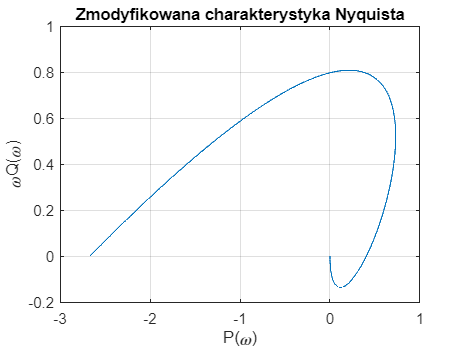


figure
plot(P(:, :), w.*Q(:, :)');
grid on;
title('Zmodyfikowana charakterystyka Nyquista');
xlabel('P(\omega)');
ylabel('\omegaQ(\omega)');

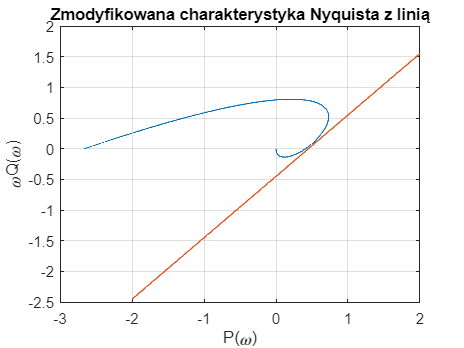


figure
plot(P(:, :), w.*Q(:, :)');
grid on;
title('Zmodyfikowana charakterystyka Nyquista z linią');
xlabel('P(\omega)');
ylabel('\omegaQ(\omega)');
hold on;
plot(x, a*x+b)


m = 1/(-b/a)

m = 2.2222

OUTSIDE THE CIRCLE


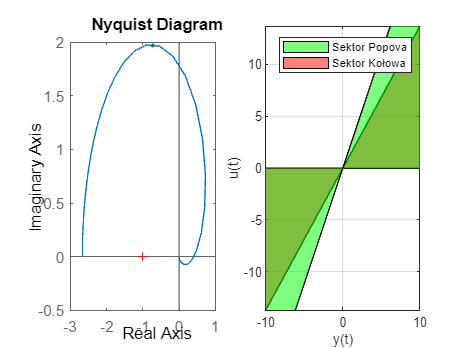

m1m2plot(m1, m2, G_L, m)

# Regulator

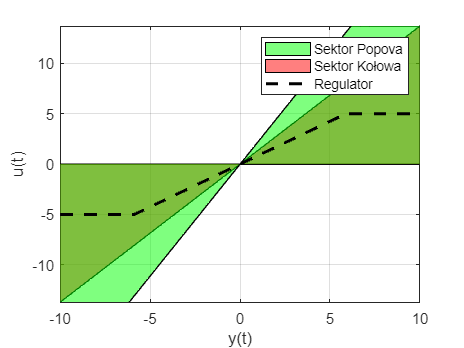

figure
%x is Y here
x = -10:0.1:10;
%y are U here
y1 = m1*x;
y2 = m2*x;

plot(x, y1, x, y2);
xlim([min(x), max(x)]);
ylim([min([y1, y2]), max([y1, y2])]);
hold on;
%Sektor kołowa
a_k = area(x,y1, 'FaceColor', 'r', 'FaceAlpha', 0.5);
area(x,y2, 'FaceColor', 'r', 'FaceAlpha', 0.5);
grid on;
hold on;
%Sektor
a_p = area(x, m*x, 'FaceColor', 'g', 'FaceAlpha', 0.5);
%Regulator
p_r = plot(x, regulator(x), "LineWidth", 2, "LineStyle","--", "Color", [0 0 0]);
legend([a_p, a_k, p_r], ["Sektor Popova", "Sektor Kołowa", "Regulator"])
xlabel("y(t)")
ylabel("u(t)")

function [u] = regulator(y)
    k = 0.85;
    umin = -5;
    umax = 5;

    %u = atan(y)*k;
    u = k * y;

    u(u > umax) = umax;
    u(u < umin) = umin;
end %

function [] = m1m2plot(m1, m2, G, m)
    plotoptions = nyquistoptions('cstprefs');
    plotoptions.ShowFullContour = 'off';
    figure;
    subplot(1, 2, 1);
    nyquistplot(G, plotoptions)

    hold on
    if(1/m1 ==0 || 1/m2 ==0 )
        if (1/m1 == 0 && 1/m2 > 0)
            fill ([-100, -100, 1/m2, 1/m2] ,[-100, +100, +100, -100] ,[0.7450 0.3010  0.9330],'FaceAlpha',0.3);
        end
        if (1/m1 < 0 && 1/m2 == 0)
            fill ([1/m1, 1/m1, 100, 100] ,[-100, +100, +100, -100] ,[0.7450 0.3010  0.9330],'FaceAlpha',0.3);
        end
    else
        theta = linspace(0, 2*pi, 100);
        y0 = 0;
        x0 = (1/m1 + 1/m2) / 2;
        v = abs(1/m1 - 1/m2) / 2;
        x = x0 + v*cos(theta);
        y = y0 + v*sin(theta);

        if(1/m1 * 1/m2 > 0)
            disp("OUTSIDE THE CIRCLE")
            fill (x ,y ,[0.3010  0.9330 0.7450],'FaceAlpha',0.3);
        else
            fill (x ,y ,[0.7450 0.3010  0.9330],'FaceAlpha',0.3);
        end

    end
    
    subplot(1, 2, 2);
    x = [-10, 10];
    y1 = m1*x;
    y2 = m2*x;

    plot(x, y1, x, y2);
    xlim(x);
    ylim([min([y1, y2]), max([y1, y2])]);
    hold on;
    a_k = area(x,y1, 'FaceColor', 'r', 'FaceAlpha', 0.5);
    area(x,y2, 'FaceColor', 'r', 'FaceAlpha', 0.5);
    grid on;
    hold on;
    a_p = area(x, m*x, 'FaceColor', 'g', 'FaceAlpha', 0.5);
    legend([a_p, a_k], ["Sektor Popova", "Sektor Kołowa"])
    xlabel("y(t)")
    ylabel("u(t)")
end